reduced_ord_state_obsv;


=== Progetto Osservatore Ridotto ===
Polo osservatore λo = -215.83 rad/s
Guadagno osservatore L  = 182.1037

=== Verifica ===
Autovalore calcolato di Ao: -215.83 (deve essere -215.83)
Dimensioni: Ao(1x1), Bo(1x2), Co(2x1), Do(2x2) ✓


discrete_design;
motor_model_discrete;


=== Progetto Osservatore Ridotto ===
Polo osservatore λo = -215.83 rad/s
Guadagno osservatore L  = 182.1037

=== Verifica ===
Autovalore calcolato di Ao: -215.83 (deve essere -215.83)
Dimensioni: Ao(1x1), Bo(1x2), Co(2x1), Do(2x2) ✓
=== Discretizzazione ZOH Pianta (T = 10 ms) ===
Phi = 
    1.0000    0.0085
         0    0.7137

Gamma = 
    0.0084
    1.5912

H = 
     1     0

J = 0.00 (Deve essere 0 per D=0) 


Robust_design_step;

Rank controllabilità A_e,B_e = 3
Guadagni K per ciascun caso:
   1.0e+03 *

    1.0928    0.0452    0.0005
    0.4290    0.0298    0.0005
    4.7600    0.1347    0.0012
    7.1399    0.1744    0.0014





step_gain = 50;

T = 1e-3;

simOut_2_2_5_1ms = sim('Lab_2\Point_2_2\2_2_5\Discrete_PID_model.slx');

Found algebraic loop that contains: 
Discrete_PID_model/State-space controller/MatrixMultiply
Discrete_PID_model/State-space controller/Sum1
Discrete_PID_model/State-space controller/Saturation (discontinuity)
Discrete_PID_model/Discrete State-Space
Discrete_PID_model/State-space controller/rpm2rad//s
Discrete_PID_model/State-space controller/de

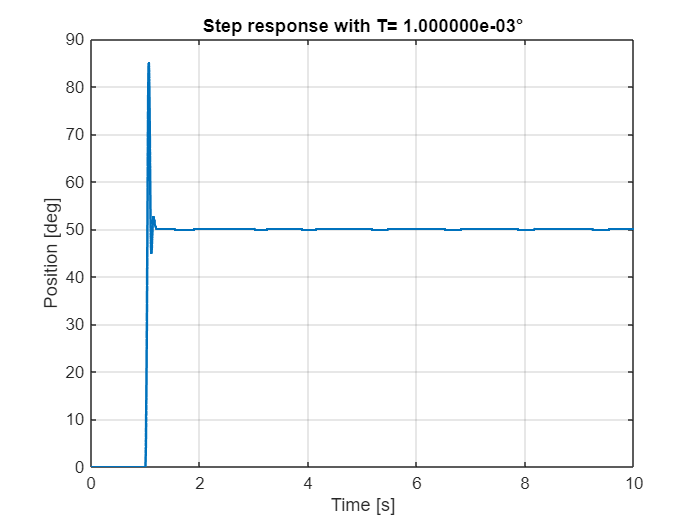


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_2_5_1ms.th.time,squeeze(simOut_2_2_5_1ms.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');

T = 10e-3;

simOut_2_2_5_10ms = sim('Lab_2\Point_2_2\2_2_5\Discrete_PID_model.slx');

Found algebraic loop that contains: 
Discrete_PID_model/State-space controller/MatrixMultiply
Discrete_PID_model/State-space controller/Sum1
Discrete_PID_model/State-space controller/Saturation (discontinuity)
Discrete_PID_model/Discrete State-Space
Discrete_PID_model/State-space controller/rpm2rad//s
Discrete_PID_model/State-space controller/de

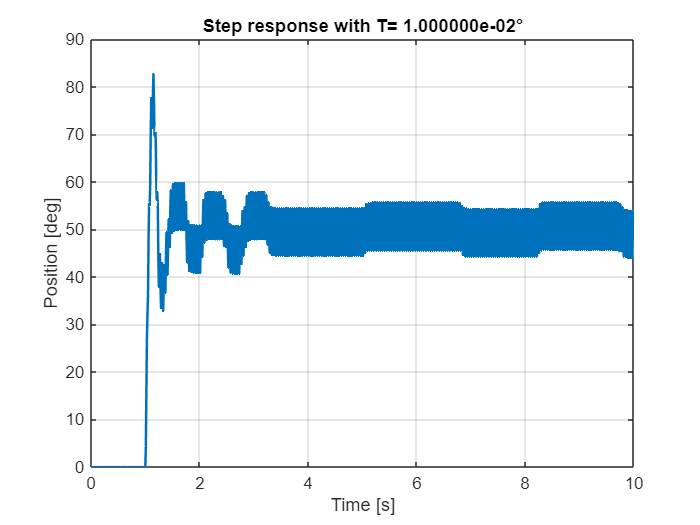


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_2_5_10ms.th.time,squeeze(simOut_2_2_5_10ms.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');



T = 50e-3;

simOut_2_2_5_50ms = sim('Lab_2\Point_2_2\2_2_5\Discrete_PID_model.slx');

Found algebraic loop that contains: 
Discrete_PID_model/State-space controller/MatrixMultiply
Discrete_PID_model/State-space controller/Sum1
Discrete_PID_model/State-space controller/Saturation (discontinuity)
Discrete_PID_model/Discrete State-Space
Discrete_PID_model/State-space controller/rpm2rad//s
Discrete_PID_model/State-space controller/de

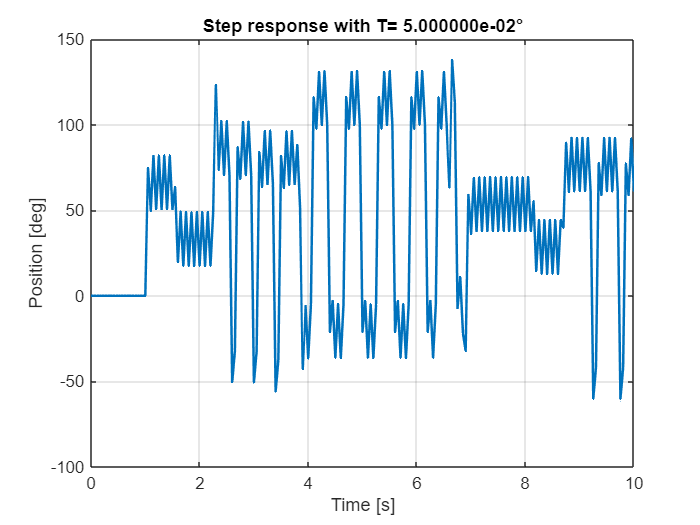


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_2_5_50ms.th.time,squeeze(simOut_2_2_5_50ms.th.signals.values), 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');